%题1
s=log(1);n=0;
while s<=100
    n=n+1;
    s=s+log(1+n);
end
fprintf("最小m值是%d",n)

最小m值是37

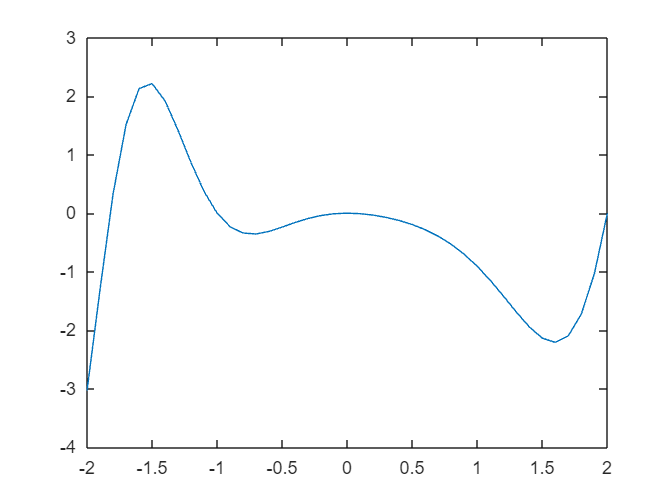

%题2.1
x=-2:0.1:2;y=x.^2.*sin(x.^2-x-2);
plot(x,y)

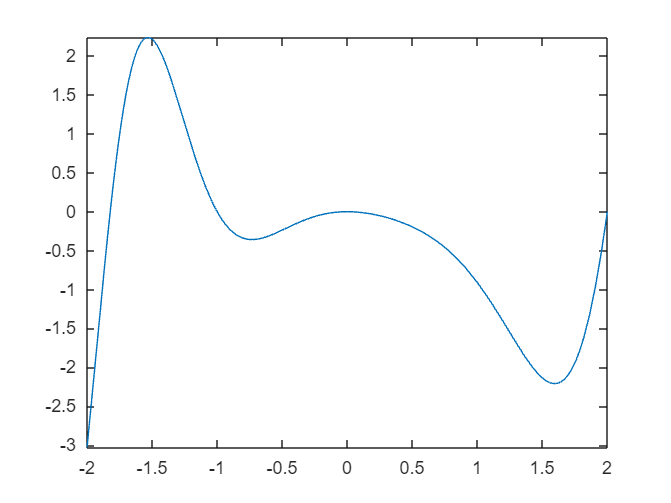

%题2.2(1)
f = @(x) x.^2 .* sin(x.^2 - x - 2);
fplot(f, [-2, 2])

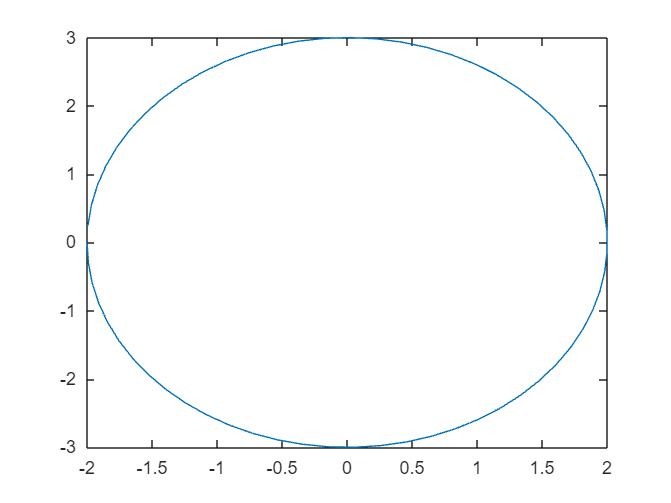

%题2.2(2)
r=-pi:0.1:pi;x=2*cos(r);y=3*sin(r);
plot(x,y)

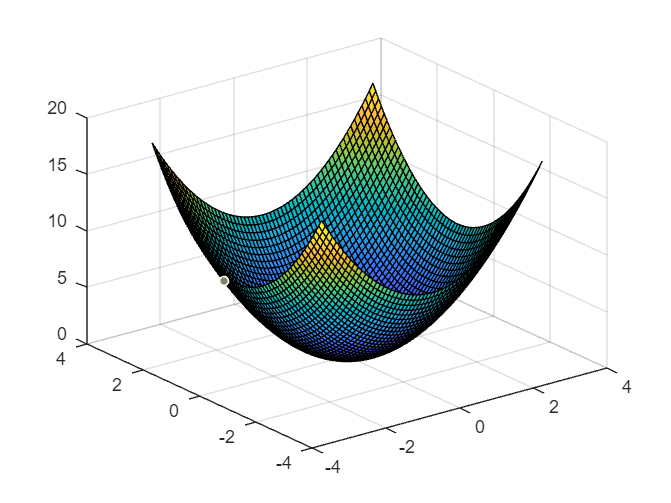

%题2.3
xa=-3:0.1:3;ya=-3:0.1:3;
[x,y]=meshgrid(xa,ya);
z=x.^2+y.^2;
surf(x,y,z);

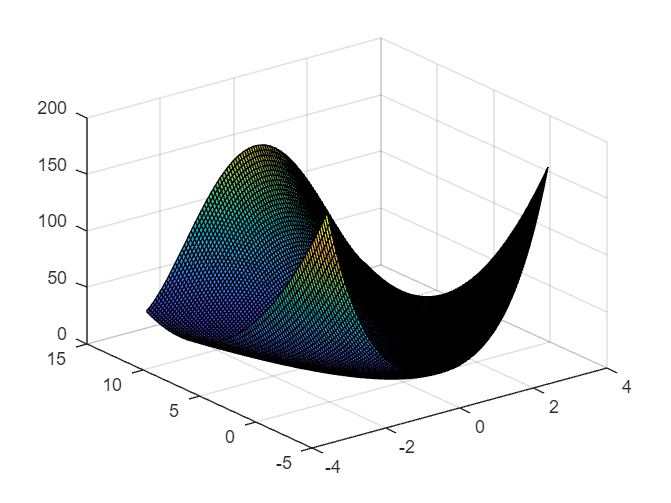

%题2.4
xa=linspace(-3,3,100);ya=linspace(-3,13,100);
[x,y]=meshgrid(xa,ya);
z=x.^4+3*x.^2+y.^2-2*x-2*y-2*x.^2.*y+6;
surf(x,y,z);

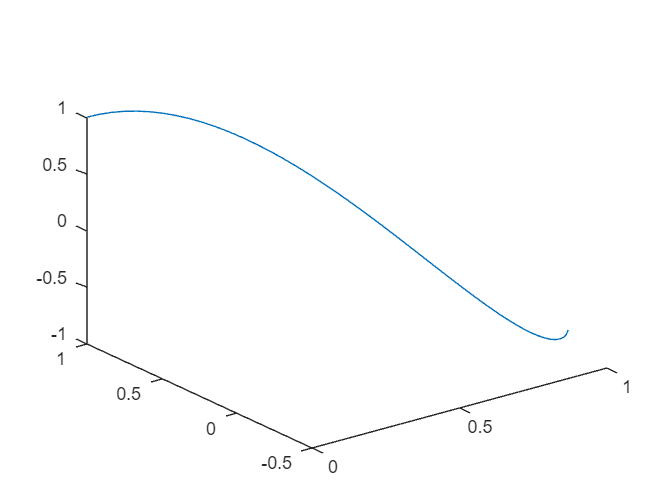

%题2.5
t=linspace(0,2,50);
x=sin(t);y=cos(t);z=cos(2*t);
plot3(x,y,z)

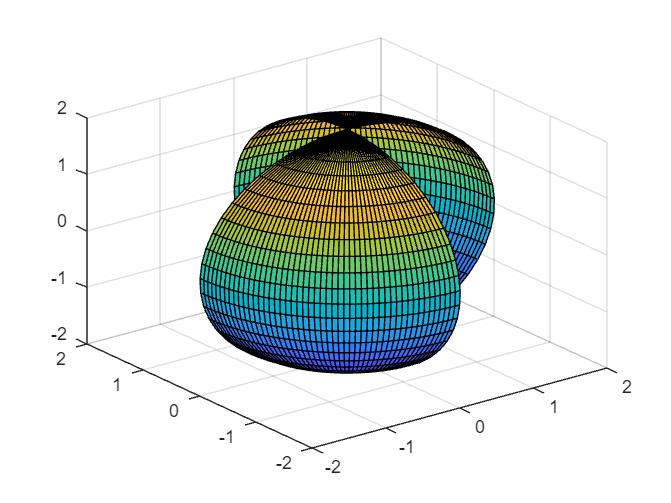

%题2.6
a=linspace(0,2*pi,50);b=linspace(0,pi/2,50);
[a,b]=meshgrid(a,b);
x=2*sin(a).*cos(b);y=2*sin(a).*sin(b);z=2*cos(a);
surf(x,y,z)

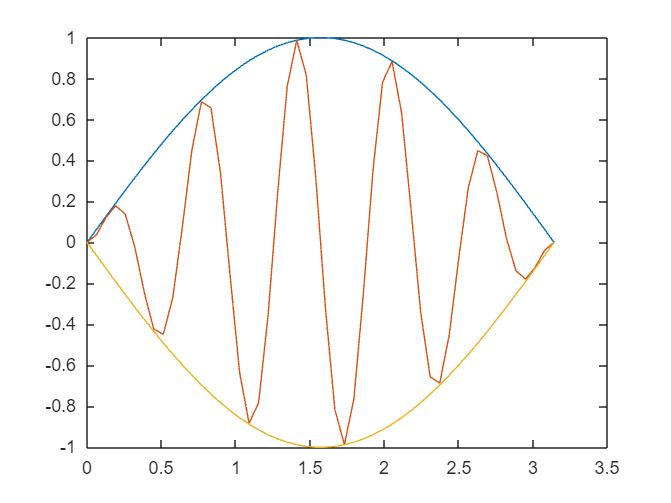

%题2.7
x=linspace(0,pi,50);y1=sin(x);
plot(x,y1);
hold on;
y2=sin(x).*sin(10*x);
plot(x,y2);
y3=-sin(x);
plot(x,y3);
hold off;

%题3
function y = g(x)
    if x >= 2
        y = x^2;
    else
        y = x + 2;
    end
end

g2 = g(2);
g_minus_2 = g(-2);

disp(['g(2) = ', num2str(g2)])

g(2) = 4


disp(['g(-2) = ', num2str(g_minus_2)])

g(-2) = 0


%题4
sum = 1;
for i = 1:10
    sum = sum * i;
end
disp(sum)

     3628800



%题5
sum = 0;
for i = 1:100
    sum = sum + i;
end
disp(sum)

        5050




clear
sum = sum(1:100);
disp(sum)

        5050



%题6
n = input('请输入该电子产品的使用寿命：');

if n < 0
    disp('输入非法！')
else
    switch n
        case num2cell(0:1000)
            disp('不合格')
        case num2cell(1000:1200)
            disp('三等品')
        case num2cell(1200:1500)
            disp('二等品')
        otherwise
            disp('一等品')
    end
end

一等品


%题7
4 < 20,4 <= 20,4 == 20,4 ~= 20

ans = logical
   1


ans = logical
   1


ans = logical
   0


ans = logical
   1


%题8
k=1;Sum=1000;
while Sum<1000000
    Sum=Sum*(1+0.06)+10000;
    k=k+1;
end
fprintf("需要%d年",k);

需要35年

clear
%题9
% 随机生成学生人数
m = randi([30, 60]);
% 创建班级

student = 包含以下字段的 struct :
    name: {[]  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []}
      id: {[]  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []}


class = struct();

% 填充学生信息和成绩
for i = 1:m
    class(i).name = ['Student ' num2str(i)];
    class(i).id = i;
    class(i).grades = randi([30, 100], 1, 5);  % 假设每个学生有5门课程
end

for i = 1:m
    total_score = sum(class(i).grades);
    average_score = total_score/5;
    fprintf('学生 %s 的总分是 %d，平均分是 %.2f\n', class(i).name, total_score, average_score);
end

学生 Student 1 的总分是 371，平均分是 74.20
学生 Student 2 的总分是 303，平均分是 60.60
学生 Student 3 的总分是 354，平均分是 70.80
学生 Student 4 的总分是 349，平均分是 69.80
学生 Student 5 的总分是 370，平均分是 74.00
学生 Student 6 的总分是 317，平均分是 63.40
学生 Student 7 的总分是 363，平均分是 72.60
学生 Student 8 的总分是 346，平均分是 69.20
学生 Student 9 的总分是 326，平均分是 65.20
学生 Student 10 的总分是 242，平均分是 48.40
学生 Student 11 的总分是 409，平均分是 81.80
学生 Student 12 的总分是 367，平均分是 73.40
学生 Student 13 的总分是 330，平均分是 66.00
学生 Student 14 的总分是 307，平均分是 61.40
学生 Student 15 的总分是 373，平均分是 74.60
学生 Student 16 的总分是 349，平均分是 69.80
学生 Student 17 的总分是 288，平均分是 57.60
学生 Student 18 的总分是 315，平均分是 63.00
学生 Student 19 的总分是 328，平均分是 65.60
学生 Student 20 的总分是 333，平均分是 66.60
学生 Student 21 的总分是 333，平均分是 66.60
学生 Student 22 的总分是 373，平均分是 74.60
学生 Student 23 的总分是 359，平均分是 71.80
学生 Student 24 的总分是 254，平均分是 50.80
学生 Student 25 的总分是 400，平均分是 80.00
学生 Student 26 的总分是 334，平均分是 66.80
学生 Student 27 的总分是 260，平均分是 52.00
学生 Student 28 的总分是 440，平均分是 88.00
学生 Student 29 的总分是 381，平均分是 76.20
学生 Student 30 的总分是 297，

%题10
s = 0.5;
r = 0;
for n = 2:2:38
    r = r + s^n;
end
r

r = 0.3333

%题10至题14请参考'D3_[11-14...].m'